%Describe Infectivty 
%%%Variables
% I0 = inital infectivity
% n = threshold of antibodies per virus 
% m = average number of antibodies per virus

I0 = 1; %inital infectivity
n = 24; %threshold of antibodies per virus
m = linspace(0,24,24); %average number of antibodies per virus 


lengthOfTime = 10; %length of time 
time = linspace(0, lengthOfTime, 10*lengthOfTime);


I = zeros(length(m),length(time)); %infectivity 

for num = 1:length(m)
    
    for allTime = 1:length(time)
        
        for r = 0:(n-1)
            
            I(num, allTime) = I(num, allTime) + (m(num)^r) * exp(-m(num)) / factorial(r);
        
        end
        
    end
    
end

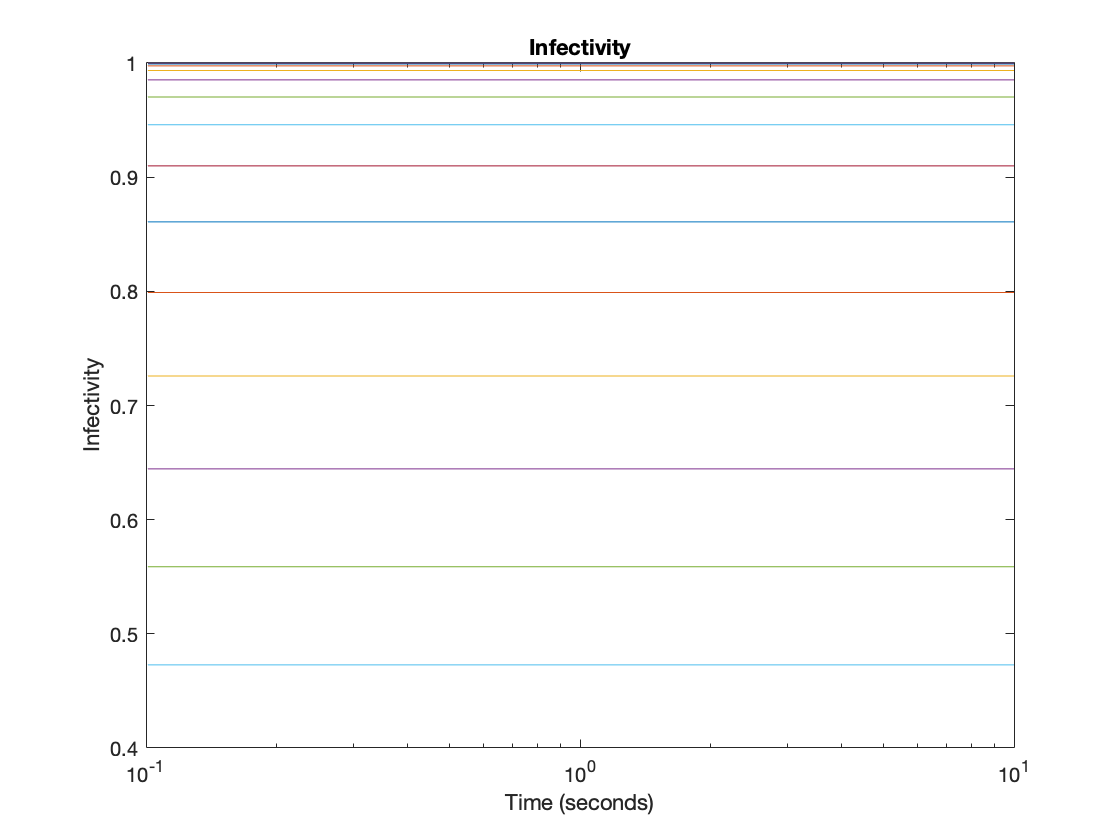

hold on
for eachPlot = 1:length(m)
    semilogx(time, I(eachPlot,:))
end
hold off
xlabel("Time (seconds)")
ylabel("Infectivity")
title("Infectivity")